# Find Weights

High Baseline Model

lb = 10^-5;
ub = 60;
ub_neg = -30;
% s_x = randstart(12,lb,ub)
% s_w = randstart(2,ub_neg,ub)
% s_w2 = [-47.9581 -29.3471];
%       s_x2 = [33.5761 56.7630 58.6119 0.1153 59.9942 56.4312 4.3897 7.6217 50.1281 16.2599 0.9777 54.8493]
%d = load("ga_solution2.mat");
%s_x3 = d.solution.x;
%s_x3

% Create optimization variables
x5 = optimvar("x",1,14,"LowerBound",lb,"UpperBound",ub);

% Set initial starting point for the solver
initialPoint4.x = zeros(size(x5));

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@Error,x5);

% Define problem constraints
problem.Constraints = nlcon2(x5);

% Set nondefault solver options
options4 = optimoptions("ga","Display","iter","MutationFcn",...
    "mutationadaptfeasible","UseParallel",true,"PlotFcn",["gaplotscores",...
    "gaplotbestf"]);

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       x

	minimize :
       Error(x)


	subject to :
       arg_LHS <= zeros(1, 5)

       where:

             arg1 = zeros(1, 5);
             arg9 = (x(4) .* x(6));
             arg14 = (((x(12) .* x(4)) .* x(7)) .* x(9));
             arg19 = (((x(12) .* x(4)) .* x(8)) .* x(11));
             arg25 = ((((((-1) + (x(12) .* x(3))) + ((x(12) .* x(4)) .* x(5))) + arg9) - arg14) - arg19);
             arg1(1) = (1e-05 + (arg25 + ((((x(12) .* x(4)) .* x(7)) .* x(10)) .* x(11))));
             arg32 = ((15 .* x(3)) .* x(12));
             arg35 = ((16.51 .* x(3)) .* x(12));
             arg39 = (((16.51 .* x(4)) .* x(5)) .* x(12));
             arg44 = ((((16.51 .* x(4)) .* x(8)) .* x(11)) .* x(12));
             arg45 = ((((((76.51 - ((25 .* x(4)) .* x(6))) - ((16.51 .* x(4)) .* x(6))) - arg32) - arg35) - arg39) + arg44)


% Solve problem
[solution,objectiveValue3,reasonSolverStopped2] = solve(problem,initialPoint4,...
    "Solver","ga","Options",options4);

Starting parallel pool (parpool) using the 'Processes' profile ...



Solving problem using ga.

Single objective optimization:
14 Variable(s)
5 Nonlinear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible



                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations



% Display results
solution
reasonSolverStopped2
objectiveValue3

% Clear variables
clearvars x5 initialPoint4 options4 reasonSolverStopped2 objectiveValue3

%objectiveValue = 10^6;
%while objectiveValue >= 10^6
    %s_x = randstart(12,lb,ub)
    %s_w = randstart(2,ub_neg,ub)
    d = load("ga_solution2.mat");
    s_x = d.solution.x;
    s_w = d.solution.W23;

    % Create optimization variables
x2 = optimvar("x",1,12,"LowerBound",lb,"UpperBound",ub);
W232 = optimvar("W23",1,2,"LowerBound",ub_neg,"UpperBound",ub);

% Set initial starting point for the solver
initialPoint.x = s_x;
initialPoint.W23 = s_w;

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@Error,x2,W232);

% Define problem constraints
problem.Constraints = nlcon2(x2,W232);

% Set nondefault solver options
options2 = optimoptions("fmincon","Algorithm","active-set","PlotFcn",...
    "optimplotfvalconstr");

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       W23, x

	minimize :
       arg1

       where:

           arg1 = Error(x, W23);


	subject to :
       arg_LHS <= zeros(1, 5)

       where:

             arg1 = zeros(1, 5);
             arg9 = (x(4) .* x(6));
             arg14 = (((W23(1) .* x(4)) .* x(7)) .* x(9));
             arg19 = (((W23(1) .* x(4)) .* x(8)) .* x(11));
             arg25 = ((((((-1) + (W23(1) .* x(3))) + ((W23(1) .* x(4)) .* x(5))) + arg9) - arg14) - arg19);
             arg1(1) = (1e-05 + (arg25 + ((((W23(1) .* x(4)) .* x(7)) .* x(10)) .* x(11))));
             arg32 = ((15 .* x(3)) .* W23(1));
             arg35 = ((16.51 .* x(3)) .* W23(1));
             arg39 = (((16.51 .* x(4)) .* x(5)) .* W23(1));
             arg44 = ((((16.51 .* x(4)) .* x(8)) .* x(11)) .* W23(1));
             arg45 = ((((((76.51 - ((25 .* x(4)) .* x(6))) - ((1

Solving problem using fmincon.
No active inequalities.

Local minimum possible. Constraints satisfied.

fmincon stopped because the predicted change in the objective function
is less than the value of the function tolerance and constraints 
are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


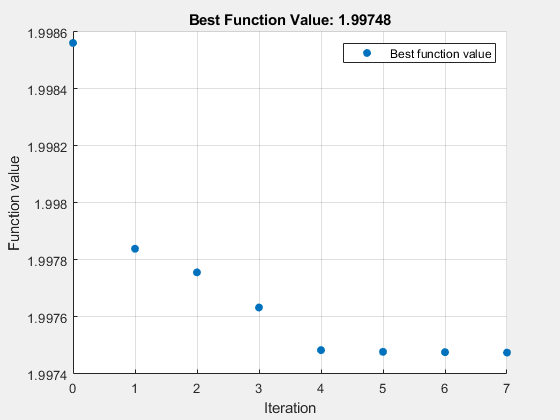


% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","fmincon","Options",options2);


% Display results
solution

solution = struct with fields:
    W23: [-0.4772 -0.9020]
      x: [1.2483 1.0477 60.0000 32.5442 1.3393 0.0028 1.3955 0.2554 0.5730 0.6714 1.1336 5.3125]


reasonSolverStopped

reasonSolverStopped =     NoDecreaseAlongSearchDirection


objectiveValue

objectiveValue = 1.9975


% Clear variables
clearvars x2 W232 initialPoint options2 reasonSolverStopped
% Display results
    solution

solution = struct with fields:
    W23: [-0.4772 -0.9020]
      x: [1.2483 1.0477 60.0000 32.5442 1.3393 0.0028 1.3955 0.2554 0.5730 0.6714 1.1336 5.3125]


    objectiveValue

objectiveValue = 1.9975

T = [8 25 20 15 16.51];
    Ba = [55 18.5 7.25 7.25 25 22.7]./1000; 
    M = [200 300 200 200 500]./1000;
e = Error(solution.x)

e = 1.9986

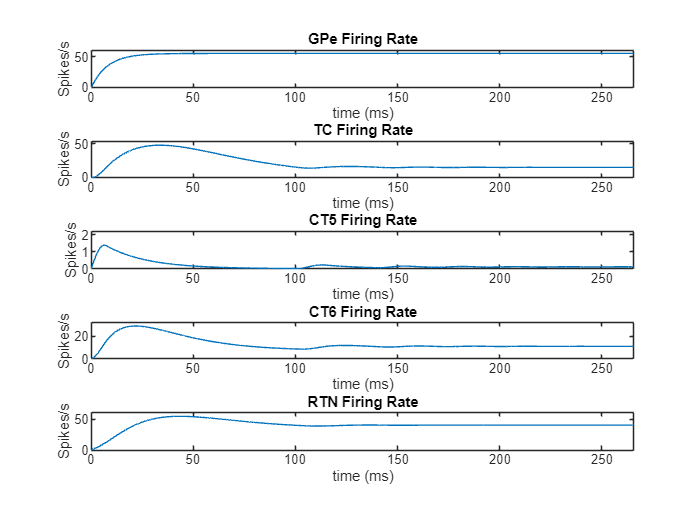

w = zeros(6);
    w(1,2) = solution.x(1);    
    w(1,6) = solution.x(2);
    w(3,2) = solution.x(3);
    w(3,4) = solution.x(4);
    w(4,2) = solution.x(5);
    w(4,3) = solution.x(6);
    w(4,5) = solution.x(7);
    w(4,6) = solution.x(8);
    w(5,2) = solution.x(9);
    w(5,6) = solution.x(10);
    w(6,2) = solution.x(11);
    w(2,3) = solution.x(12);
 v = zeros(6);
    v(1,2) = solution.x(1);
    v(1,6) = solution.x(2);
    v(3,2) = solution.x(3); 
    v(3,4) = solution.x(4);
    v(4,2) = solution.x(13);
    v(4,3) = solution.x(6);
    v(4,5) = solution.x(7);
    v(4,6) = solution.x(8);
    v(5,2) = solution.x(9);
    v(5,6) = solution.x(10);
    v(6,2) = solution.x(14);
    v(2,3) = solution.x(12); 
[t1,y1,period0,SS] = Model(zeros(5,1),w,T,Ba,M);

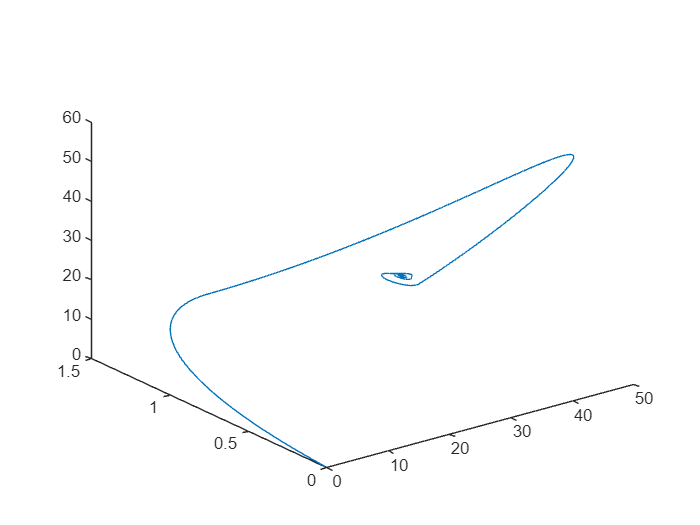

nlcon(solution.x,solution.W23)
nlcon2(solution.x,solution.W23)
figure;
plot3(1000*y1(2,:),1000*y1(3,:),1000*y1(5,:))

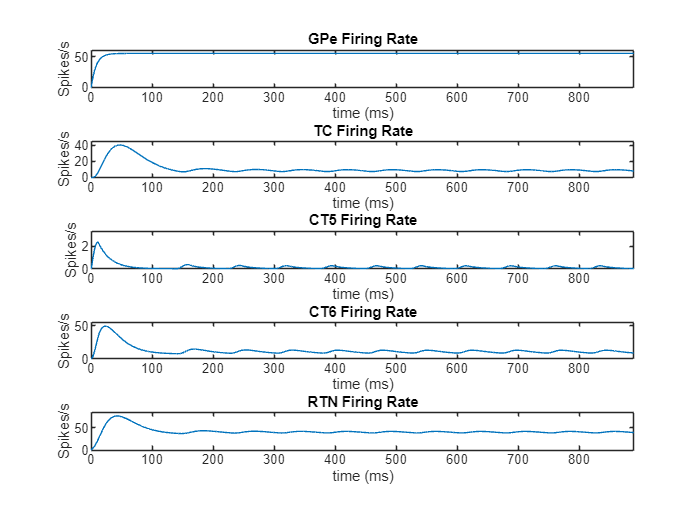

[t2,y2,period] = Model(zeros(5,1),v,T,Ba,M);

1000/period

ans = 13.6526

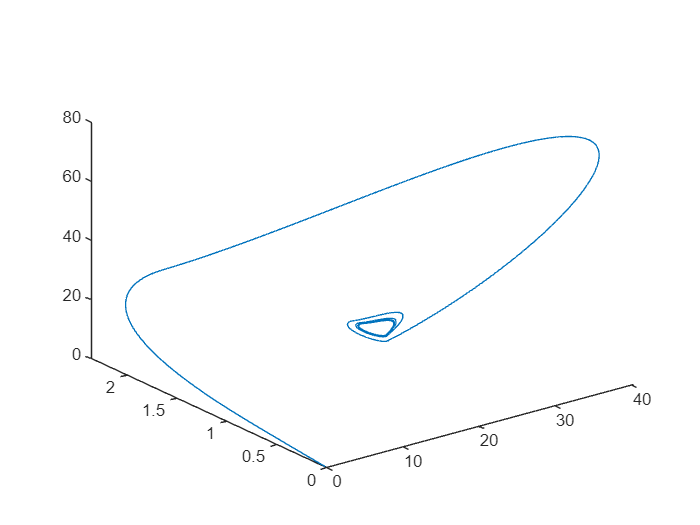

figure;
plot3(1000*y2(2,:),1000*y2(3,:),1000*y2(5,:))

## Supporting Functions

function w = randstart(n,lb,ub)
    w = rand([1,n]) * (ub-lb) + lb;
end

function [t,y,period,SS,flag]=Model(y0,w,T,Ba,M,varargin)
tic
N=10^6;
opt_graph=1;
opt_rplot = 0;
opt_debug = 0;
SS_check=0;
ss_flag=0;
period=0;
TOL=10^-7;
stp=.01;
h=0;
flag=0;
E=zeros(5,5^3);

% w(1,2) = W(1);
% w(6,2) = W(2);
% w(1,6) = W(3);
% w(3,2) = W(4);
% w(3,6) = W(5);
% w(4,2) = W(6);
% w(4,6) = W(7);
% w(5,2) = W(8);
% w(4,3) = W(9);
% w(3,4) = W(10);
% w(4,5) = W(11);
% w(2,3) = W23;

Ba(2) = Ba(2)-w(6,2)*Ba(6); Ba(6)=[]; %interneuron relay
for ii=1:5
    B(ii,:)=[0 Ba(ii) M(ii)];
end
numvarargs= length(varargin);
if numvarargs~=0
    for k1=1:numvarargs
        if strcmp(varargin{k1},'graphless')
            opt_graph=0;
        elseif strcmp(varargin{k1},'ss_check')
            SS_check = 1;
        elseif strcmp(varargin{k1},'debug')
            opt_debug = 1;
            opt_rplot = 1;
        else
            error(['"',num2str(varargin{k1}),'"', ' ', 'is not a valid option!'])
        end
    end
end
D=cell(3,3,3,3,3);
V=cell(3,3,3,3,3);
Beta=cell(3,3,3,3,3);
ss=cell(3,3,3,3,3);

f(1:3,1:5)  =...
    [-1 0 0 0 0;...
    -1 0 0 0 0;...
    -1 0 0 0 0];
f(1:3,6:10) =...
    [0 -1 0 0 0;...
    -w(1,2)+w(6,2)*w(1,6) -1 w(3,2) w(4,2)-w(6,2)*w(4,6) -w(5,2)+w(6,2)*w(5,6);...
    0 -1 0 0 0];
f(1:3,11:15)=...
    [0 0 -1 0 0;...
    0 w(2,3) -1 w(4,3) 0;...
    0 0 -1 0 0];
f(1:3,16:20)=...
    [0 0 0 -1 0;...
    0 0 w(3,4) -1 0;...
    0 0 0 -1 0];
f(1:3,21:25)=...
    [0 0 0 0 -1;...
    0 0 0 w(4,5) -1;...
    0 0 0 0 -1];
kk=1;
for i1=1:3
    for i2=1:3
        for i3=1:3
            for i4=1:3
                for i5=1:3
                    A=[1/T(1)*f(i1,1:5);1/T(2)*f(i2,6:10);1/T(3)*f(i3,11:15);1/T(4)*f(i4,16:20);1/T(5)*f(i5,21:25)];
                    [V{i1,i2,i3,i4,i5},D{i1,i2,i3,i4,i5}]=eig(A);
                    E(1:5,kk) = eig(A);
                    kk=kk+1;
                    Beta{i1,i2,i3,i4,i5}=[B(1,i1);B(2,i2);B(3,i3);B(4,i4);B(5,i5)];
                    ss{i1,i2,i3,i4,i5}=A\-diag([1/T(1),1/T(2),1/T(3),1/T(4),1/T(5)])*Beta{i1,i2,i3,i4,i5};                    
                end
            end
        end
    end
end
%D{2,2,2,2,2}
if SS_check
    SS = ss{2,2,2,2,2};
    if length(find(abs(real(E))<10^(-12)))>=19 %1
        flag=1;
    end
    t=0;
    y=0;
    return
end
y(:,1)=y0;
t(1)=0;
J=zeros(5,1);
I0=([f(2,1:5);f(2,6:10);f(2,11:15);f(2,16:20);f(2,21:25)]+eye(5))*y(:,1)+Ba';
for i0=1:5
    if I0(i0)>=M(i0)
        J(i0)=3;
    elseif I0(i0)<=0
        J(i0)=1;
    else
        J(i0)=2;
    end
end
if opt_debug
    disp("Intial Region " + num2str(J'));
end
k=1;
limitcheck=[y0' 0];
while k<N
    [t1,y1]=compute(y(:,k));
    y=[y y1(:,2:end)];

    t=[t t1(2:end)+t(end)];
    k=numel(t);
    limitcheck=[limitcheck; y(:,end)' t(end)];

    for lct=1:size(limitcheck,1)-1
        if abs(limitcheck(lct,1:end-1)-limitcheck(end,1:end-1))<TOL
            period=(limitcheck(end,end)-limitcheck(lct,end));
            %fprintf('Loop Detected at N=%d\n',k)
            k=N;
        end
    end
    if ss_flag
        k=N;
    end
    SS = ss;
end
if opt_graph
    figure%(Position=[300,544,1500,1000]);
    nucleiname={'GPe','TC','CT5','CT6','RTN'};
    for ii=1:5
        %nexttile;
        subplot(5,1,ii)
        plot(t,1000.*y(ii,:))
        if opt_rplot
            ax = gca;
            hold on
            if size(limitcheck,1) >2
                plot(repmat(limitcheck(2:end-1,end),[1,2]),[0 ax.YLim(2)],'k')
            end
        end
        title([nucleiname{ii},' Firing Rate'])
        xlabel('time (ms)')
        ylabel('Spikes/s')
        axis([0 t(end) 0 ceil(max(1000.*y(ii,:)))+.1*ceil(max(1000.*y(ii,:)))])
    end
end
    function [t,y]=compute(y0)
        Plane{1}={@(t,alpha) Ba(1)-alpha*M(1)};
        Plane{2}={@(t,alpha) (-w(1,2)+w(6,2)*w(1,6))*planecor(1,t)+(w(3,2))*planecor(3,t)+(w(4,2)-w(6,2)*w(4,6))*planecor(4,t)+(-w(5,2)+w(6,2)*w(5,6))*planecor(5,t)+Ba(2)-alpha*M(2)};
        Plane{3}={@(t,alpha) w(2,3)*planecor(2,t)+w(4,3)*planecor(4,t)+Ba(3)-alpha*M(3)};
        Plane{4}={@(t,alpha) w(3,4)*planecor(3,t)+Ba(4)-alpha*M(4)};
        Plane{5}={@(t,alpha) w(4,5)*planecor(4,t)+Ba(5)-alpha*M(5)};

        
        C=@(t) diag([exp(D{J(1),J(2),J(3),J(4),J(5)}(1,1)*t),...
            exp(D{J(1),J(2),J(3),J(4),J(5)}(2,2)*t),exp(D{J(1),J(2),J(3),J(4),J(5)}(3,3)*t),...
            exp(D{J(1),J(2),J(3),J(4),J(5)}(4,4)*t),exp(D{J(1),J(2),J(3),J(4),J(5)}(5,5)*t)]);
        c=(V{J(1),J(2),J(3),J(4),J(5)}*C(0))\(y0-ss{J(1),J(2),J(3),J(4),J(5)});
        t(1)=0;
        t(2)=t(1)+stp;
        sum0=sum(J);
        y(:,1)=y0;
        j=2;
        intJ=J;
        stk=0;
        while j<=N-k+1
            y(:,j)=real(V{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}*C(t(j))*c+ss{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)});
            I=([f(2,1:5);f(2,6:10);f(2,11:15);f(2,16:20);f(2,21:25);]+eye(5))*y(:,j)+Ba';
            for l=1:5
                if I(l)>=M(l)
                    J(l)=3;
                elseif I(l)<=0
                    J(l)=1;
                else
                    J(l)=2;
                end
            end
            if j>5
                ss_check=y(:,j)-y(:,j-1)+y(:,j)-y(:,j-2)+y(:,j)-y(:,j-3);
                if abs(ss_check)<TOL
                    ss_flag=1;
                    break
                end
            end
            i=find(J~=intJ);
            if ~isempty(i)
                if length(i)>1 || (abs(J(i)-intJ(i))>1)
                    t(j)=t(j)-.9*(t(j)-t(j-1));
                    stk=stk+1;
                    continue
                end
                if opt_debug
                    disp("Region " + num2str(J'));
                end
                if (intJ(i)==3) || (J(i)==3)
                    alpha=1;
                else
                    alpha=0;
                end
                g=cell2mat(Plane{i});
                g1= @(s) g(s,alpha);
                tstart=fzero(g1,[t(j-1) t(j)]);
                y0=real(V{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}*C(tstart)*c+ss{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)});
                y(:,j)=y0;
                t(j)=tstart;
                break
            else
                if j+1<=N-k+1
                    t(j+1)=t(j)+stp;
                end
                j=j+1;
            end
        end
        function X=planecor(i,t)
            X=real(c(1)*V{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}(i,1)*exp(D{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}(1,1)*t)+...
                c(2)*V{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}(i,2)*exp(D{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}(2,2)*t)+...
                c(3)*V{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}(i,3)*exp(D{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}(3,3)*t)+...
                c(4)*V{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}(i,4)*exp(D{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}(4,4)*t)+...
                c(5)*V{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}(i,5)*exp(D{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}(5,5)*t)+...
                ss{intJ(1),intJ(2),intJ(3),intJ(4),intJ(5)}(i));
        end
    end
end

function [w,T,Ba,M] = randweights(tf)
if nargin <1
    tf = false;
end
   w=nan(6);
   w(1,2) = randi(30);
   w(6,2) = randi(30);
   w(1,6) = randi(30);
   w(3,2) = randi(30);
   w(5,6) = randi(30);
   w(4,2) = randi(30);
   w(4,6) = randi(30);
   w(5,2) = randi(30);
   w(4,3) = randi(30);
   w(3,4) = randi(30);
   w(4,5) = randi(30);
   %w1 = randi(30);
   %w2 = randi(30);
   %w(2,3) = w1-w2;
   w(2,3) = randi(30);
   T = 15*rand(1,5);
   Ba = [60+0 10 2 2 10 10] + [0 6*(rand(1,5)-.5)];
   M = [300 200 200 200 200] + [0 5*(rand(1,4)-.5)];
   M = M./1000;
   Ba = Ba./1000;
   % Removed the extra conditional. This gives us weights with middle det(A)<0
   while(and(tf,...
           ~((-1+w(2,3)*w(3,2)+w(2,3)*w(3,4)*w(4,2)+w(3,4)*w(4,3) ...
           -w(2,3)*w(3,4)*w(4,5)*w(5,2)-w(2,3)*w(3,4)*w(4,6)*w(6,2) ...
           +w(2,3)*w(3,4)*w(4,5)*w(5,6)*w(6,2)) < 0)))
       %|| isequal(conditions1(w,T), [1 1 1]))))
       %        w(1,2) = randi(30);
       %        w(6,2) = randi(30);
       %        w(1,6) = randi(30);
       %        w(3,2) = randi(30);
       %        w(5,6) = randi(30);
       %        w(4,2) = randi(30);
       %        w(4,6) = randi(30);
       %        w(5,2) = randi(30);
       %        w(4,3) = randi(30);
       %        w(3,4) = randi(30);
       %        w(4,5) = randi(30);
       %        w(2,3) = randi(30);
       w = 30 * rand(6); %cleaner code, even if it generates more numbers
   end
end

function q = SS_test(ss,M)
    q = isequal(and(ss>zeros(5,1),ss<M'),ones(5,1));
end

function [w,T,Ba,M] = SearchWeights()
t1=tic;
warning('off','MATLAB:nearlySingularMatrix')
q=0;
i=0;

while ~q
    [w,T,Ba,M] = randweights(1);
    [~,~,~,ss,flag]=Model(zeros(5,1),w,T,Ba,M,'graphless','ss_check');
    if flag
        disp("Noninvertible")
        continue
    end
    q = SS_test(ss,M);
    if i == 100000
        disp("Found no solutions")
        w=[];
        T=[];
        Ba=[];
        M=[];
        break
    end
    i=i+1;
end
toc(t1);
end

function Q = conditions(w,T)
q(1)=(T(1)*T(2)*(T(3)*(T(4)+T(5))+T(4)*T(5))+T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*...
    T(4)*T(5))*(T(1)^2*(T(2)^2*(T(3)+T(4))*(T(3)*(T(4)+T(5))+T(5)*(T(4)-T(5)*...
    w(3,4)*w(4,3)+T(5)))+T(2)*(T(3)^2*(T(4)+T(5))^2+T(3)*T(4)*T(5)*(2*T(4)+...
    T(5)*(w(3,4)*w(2,3)*(w(4,2)+w(4,6)*w(6,2))+2))+T(4)^2*T(5)^2*(-(w(3,2)*w(2,3))+...
    w(3,6)*w(6,2)*w(2,3)+1))+T(3)*T(4)*T(5)*(T(3)*(T(4)+T(5))+T(4)*T(5)*...
    (-(w(3,2)*w(2,3))+w(3,6)*w(6,2)*w(2,3)+1)))+T(1)*(T(2)*T(3)*(T(4)+T(5))+T(2)*...
    T(4)*T(5)+T(3)*T(4)*T(5))^2+T(2)*T(3)*T(4)*T(5)*(T(2)*T(3)*(T(4)+T(5))+...
    T(2)*T(4)*T(5)+T(3)*T(4)*T(5)))>0;

q(2)=((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*...
    (T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*...
    T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)...
    *T(5)*(1-w(3,2)*w(2,3)+w(3,6)*w(6,2)*w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*...
    (T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(4)*T(5)*w(3,6)*...
    w(6,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-...
    T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(4)*w(3,6)*w(6,2)*w(2,3)+...
    T(5)*w(3,6)*w(6,2)*w(2,3)-T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))-T(1)*T(2)*T(3)*T(4)*...
    T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*...
    w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(4)*T(5)*w(3,6)*w(6,2)*w(2,3)+T(1)*(T(2)+T(3)+...
    T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*...
    w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(4)*w(3,6)*w(6,2)*w(2,3)+T(5)*w(3,6)*w(6,2)*...
    w(2,3)-T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))^2+T(1)*T(2)*T(3)*T(4)*T(5)*(T(1)*T(3)*...
    T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*...
    (1-w(3,2)*w(2,3)+w(3,6)*w(6,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)+w(4,6)*...
    w(6,2))*w(2,3)))-(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*...
    T(5)+T(3)*(T(4)+T(5))))^2*(T(1)+T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-...
    T(5)*w(3,4)*w(4,3)-T(1)*w(3,2)*w(2,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*...
    w(3,4)*w(4,2)*w(2,3)+T(1)*w(3,6)*w(6,2)*w(2,3)+T(4)*w(3,6)*w(6,2)*w(2,3)+T(5)*w(3,6)*...
    w(6,2)*w(2,3)-T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)-T(1)*w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*...
    w(5,2)+w(4,6)*w(6,2))*w(2,3))))/((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+...
    T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+...
    T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-...
    T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2)*w(2,3)+w(3,6)*w(6,2)*w(2,3)))-T(1)*...
    T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+...
    T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(4)*T(5)*w(3,6)*w(6,2)*w(2,3)+...
    T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*...
    w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(4)*w(3,6)*w(6,2)*w(2,3)+T(5)*...
    w(3,6)*w(6,2)*w(2,3)-T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3))))>0;

q(3)=((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*...
    (T(4)+T(5))))^2*(T(1)+T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*...
    w(3,4)*w(4,3)-T(1)*w(3,2)*w(2,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*...
    w(4,2)*w(2,3)+T(1)*w(3,6)*w(6,2)*w(2,3)+T(4)*w(3,6)*w(6,2)*w(2,3)+T(5)*w(3,6)*w(6,2)*...
    w(2,3)-T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)-T(1)*w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)+...
    w(4,6)*w(6,2))*w(2,3)))^2+(1-w(3,2)*w(2,3)+w(3,6)*w(6,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-...
    w(4,5)*w(5,2)+w(4,6)*w(6,2))*w(2,3)))*((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*...
    T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*...
    T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+...
    T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2)*w(2,3)+w(3,6)*w(6,2)*w(2,3)))^2-...
    T(1)*T(2)*T(3)*T(4)*T(5)*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+...
    T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+...
    T(1)*T(4)*T(5)*(1-w(3,2)*w(2,3)+w(3,6)*w(6,2)*w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+...
    T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(4)*T(5)*...
    w(3,6)*w(6,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*...
    w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(4)*w(3,6)*w(6,2)*...
    w(2,3)+T(5)*w(3,6)*w(6,2)*w(2,3)-T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))+T(1)^2*T(2)^2*T(3)^2*...
    T(4)^2*T(5)^2*(1-w(3,2)*w(2,3)+w(3,6)*w(6,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*...
    w(5,2)+w(4,6)*w(6,2))*w(2,3))))+(T(1)+T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-...
    T(5)*w(3,4)*w(4,3)-T(1)*w(3,2)*w(2,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*...
    w(4,2)*w(2,3)+T(1)*w(3,6)*w(6,2)*w(2,3)+T(4)*w(3,6)*w(6,2)*w(2,3)+T(5)*w(3,6)*w(6,2)*w(2,3)-...
    T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)-T(1)*w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)+...
    w(4,6)*w(6,2))*w(2,3)))*(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*...
    (T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*...
    (T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*...
    w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2)*w(2,3)+w(3,6)*w(6,2)*w(2,3)))*(T(3)*T(4)+T(3)*T(5)+...
    T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+...
    T(4)*T(5)*w(3,6)*w(6,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-...
    T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(4)*...
    w(3,6)*w(6,2)*w(2,3)+T(5)*w(3,6)*w(6,2)*w(2,3)-T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3))))+T(1)*...
    T(2)*T(3)*T(4)*T(5)*((T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-...
    T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(4)*T(5)*w(3,6)*w(6,2)*w(2,3)+T(1)*...
    (T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-...
    T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(4)*w(3,6)*w(6,2)*w(2,3)+T(5)*w(3,6)*w(6,2)*...
    w(2,3)-T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))^2-2*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*...
    T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-w(3,2)*w(2,3)+w(3,6)*w(6,2)*...
    w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)+w(4,6)*w(6,2))*w(2,3))))))/...
    (-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*...
    (T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*...
    T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*...
    T(5)*(1-w(3,2)*w(2,3)+w(3,6)*w(6,2)*w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*...
    (T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(4)*T(5)*w(3,6)*...
    w(6,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-...
    T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(4)*w(3,6)*w(6,2)*w(2,3)+T(5)*...
    w(3,6)*w(6,2)*w(2,3)-T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3))))+T(1)*T(2)*T(3)*T(4)*T(5)*...
    (T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-...
    T(4)*T(5)*w(3,2)*w(2,3)+T(4)*T(5)*w(3,6)*w(6,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-...
    T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*...
    w(3,4)*w(4,2)*w(2,3)+T(4)*w(3,6)*w(6,2)*w(2,3)+T(5)*w(3,6)*w(6,2)*w(2,3)-T(5)*w(3,4)*...
    w(4,6)*w(6,2)*w(2,3)))^2+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*...
    (T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(1)*T(2)*T(3)*T(4)*T(5)*(-1+w(3,2)*w(2,3)-...
    w(3,6)*w(6,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)+w(4,6)*w(6,2))*w(2,3)))+...
    (T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*...
    (T(4)+T(5))))*(T(1)+T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*...
    w(4,3)-T(1)*w(3,2)*w(2,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(1)*...
    w(3,6)*w(6,2)*w(2,3)+T(4)*w(3,6)*w(6,2)*w(2,3)+T(5)*w(3,6)*w(6,2)*w(2,3)-T(5)*w(3,4)*...
    w(4,6)*w(6,2)*w(2,3)-T(1)*w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)+w(4,6)*w(6,2))*w(2,3)))))>0;

q(4) %det

Q = all(q);
end


### Error Function

function e = Error(x) 
    b = 22.7;
    y_Hthy_data = [73.5 15.15 19.133 16.008 40]'; 
    y_Hthy_SD = [18.1 2.9334 19.078 21.387 2]';
    y_PD_data = [78.1 8.6364 13.554 8.37 40]';
    y_PD_SD = [17.9 1.44 14.57 7.972 2]';

    T = [8 25 20 15 16.51];
    Ba = [55 18.5 7.25 7.25 25 b]./1000; 
    M = [200 300 200 200 500]./1000;

    e3=0;
    e4=0;
    ep=0;

    %%%%% Err 1: matching Hthy data %%%%%
    w = zeros(6);
    w(1,2) = x(1);
    w(1,6) = x(2);
    w(3,2) = x(3);
    w(3,4) = x(4);
    w(4,2) = x(5);
    w(4,3) = x(6);
    w(4,5) = x(7);
    w(4,6) = x(8);
    w(5,2) = x(9);
    w(5,6) = x(10);
    w(6,2) = x(11);
    w(2,3) = x(12);
    [~,y1,~,SS] = Model(zeros(5,1),w,T,Ba,M,'graphless');
    y1_last = y1(:,end).*1000;
    e1 = sum(((y1_last(2:end) - y_Hthy_data(2:end))./y_Hthy_SD(2:end)).^2);

    if ~and(all(SS{2,2,2,2,2}<M),all(SS{2,2,2,2,2}>0))
        e3 = 10^6;
    end

    %%%%% Err 2: matching PD data %%%%%
    v = zeros(6);
    v(1,2) = x(1);
    v(1,6) = x(2);
    v(3,2) = x(3);  % w32PD
    v(3,4) = x(4);
    v(4,2) = x(13);
    v(4,3) = x(6);
    v(4,5) = x(7);
    v(4,6) = x(8);
    v(5,2) = x(9);
    v(5,6) = x(10);
    v(6,2) = x(14);
    v(2,3) = x(12);  % w23PD
    [t2,y2,period,SS]=Model(zeros(5,1),v,T,Ba,M,'graphless');
    if period ~=0
        in = find(t2-t2(end)+period>0,1);

        y2_avg = mean(y2(:,in:end),2)*1000;
        e2 = sum(((y2_avg(2:end) - y_PD_data(2:end))./y_PD_SD(2:end)).^2);
    else
        e2 = 10^6;
    end

    % at least
    if period == 0 
        ep = 10^6;
    elseif 1000/period < 13
        ep = (1000/period-13)^2;
    elseif 1000/period > 30 
        ep = (1000/period-30)^2;
    end

    if ~and(all(SS{2,2,2,2,2}<M),all(SS{2,2,2,2,2}>0))
        e4 = 10^6;
    end

    %%%%% Combine %%%%% 
    e = e1 + e2 + e3 + e4 + ep;
end

#### Det & RH stable Only

function c = nlcon(x,W23) 

    T = [8 25 20 15 16.51];

    %%%%% Healthy %%%%%
    % det<0
c(1)= 10^-5 + (-1+W23(1)*x(3)+W23(1)*x(4)*x(5)+x(4)*x(6) ...
       -W23(1)*x(4)*x(7)*x(9)-W23(1)*x(4)*x(8)*x(11) ...
       +W23(1)*x(4)*x(7)*x(10)*x(11))<=0;  

c(2)= 10^-5 + (T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2) ...
    *(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1) ...
    -T(5)*x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11) ...
    *W23(1))))/(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5)))) - (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)* ...
    T(4)*T(5)*(1-x(3)*W23(1))) <=0;

c(3)= 10^-5 - (((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)* ...
    T(4)*T(5)*(1-x(3)*W23(1)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+T(3)+ ...
    T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5) ...
    *x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1)))- ...
    T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+ ...
    T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+T(3)+T(4)+T(5)- ...
    T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5)*x(3)*W23(1)- ...
    T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1)))^2+T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)* ...
    T(5)+T(3)*(T(4)+T(5))))*(1-x(3)*W23(1)-x(4)*(x(6)+(x(5)-x(7)* ...
    x(9)-x(8)*x(11)+x(7)*x(10)*x(11))*W23(1)))-(T(1)*T(3)*T(4)*T(5) ...
    +T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+T(3) ...
    +T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5)* ...
    x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1)- ...
    T(1)*(-1+x(3)*W23(1)+x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+ ...
    x(7)*x(10)*x(11))*W23(1)))))/((T(1)*T(3)*T(4)*T(5)+T(2)* ...
    T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+ ...
    T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3)*W23(1)))-T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)* ...
    x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)* ...
    x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5)*x(3)*W23(1)- ...
    T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1))))) <=0;

c(4) = 10^-5 - (((1-x(3)*W23(1)-x(4)*(x(6)+(x(5)-x(7)*x(9)- ...
    x(8)*x(11)+x(7)*x(10)*x(11))*W23(1)))*((T(1)*T(3)*T(4)* ...
    T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))* ...
    (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+ ...
    T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)* ...
    (1-x(3)*W23(1)))^2-T(1)*T(2)*T(3)*T(4)*T(5)*(T(2)*T(4)*T(5)+T(3)* ...
    T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3)*W23(1)))*(T(3)* ...
    T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))- ...
    T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)- ...
    T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)*-T(5)*x(3)*W23(1)-T(5)*x(4) ...
    *x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1)))+T(1)^2*T(2)^2*T(3)^2* ...
    T(4)^2*T(5)^2*(1-x(3)*W23(1)-x(4)*(x(6)+(x(5)-x(7)*x(9)- ...
    x(8)*x(11)+x(7)*x(10)*x(11))*W23(1))))+(T(1)*T(3)*T(4)*T(5)+ ...
    T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1) ...
    -T(5)*x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11) ...
    *W23(1)-T(1)*(-1+x(3)*W23(1)+x(4)*(x(6)+(x(5)-x(7)*x(9) ...
    -x(8)*x(11)+x(7)*x(10)*x(11))*W23(1))))^2+(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5)*x(3) ...
    *W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1) ...
    -T(1)*(-1+x(3)*W23(1)+x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8) ...
    *x(11)+x(7)*x(10)*x(11))*W23(1))))*(-((T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4) ...
    *T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+ ...
    T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1- ...
    x(3)*W23(1)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5) ...
    -T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+T(3)+T(4)+ ...
    T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5) ...
    *x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11) ...
    *W23(1))))+T(1)*T(2)*T(3)*T(4)*T(5)*((T(3)*T(4)+T(3)*T(5)+T(4)*T(5) ...
    +T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*W23(1) ...
    +T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6) ...
    -T(4)*x(3)*W23(1)-T(5)*x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1) ...
    +T(5)*x(4)*x(8)*x(11)*W23(1)))^2-2*(T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-x(3) ...
    *W23(1)-x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+x(7) ...
    *x(10)*x(11))*W23(1))))))/(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)*+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5) ...
    +T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1) ...
    *T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3) ...
    *W23(1)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5) ...
    *x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5)*x(3) ...
    *W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1)))) ...
    +T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3) ...
    +T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*W23(1)+T(1)*(T(2) ...
    +T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3) ...
    *W23(1)-T(5)*x(3)*W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4) ...
    *x(8)*x(11)*W23(1)))^2+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5) ...
    +T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(1)*T(2)*T(3)*T(4)*T(5) ...
    *(-1+x(3)*W23(1)+x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11) ...
    +x(7)*x(10)*x(11))*W23(1)))+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*W23(1)-T(5)*x(3) ...
    *W23(1)-T(5)*x(4)*x(5)*W23(1)+T(5)*x(4)*x(8)*x(11)*W23(1) ...
    -T(1)*(-1+x(3)*W23(1)+x(4)*(x(6)+(x(5)-x(7)*x(9) ...
    -x(8)*x(11)+x(7)*x(10)*x(11))*W23(1))))))) <=0; 

    %%%%% PD %%%%%

    % det<0
c(5)= 10^-5 + (-1+W23(2)*x(12)+x(12)*x(4)*x(5)+x(4)*x(6) ...
       -x(12)*x(4)*x(7)*x(9)-x(12)*x(4)*x(8)*x(11) ...
       +x(12)*x(4)*x(7)*x(10)*x(11)) <=0;  
end

function c = nlcon2(x) 

    T = [8 25 20 15 16.51];

    %%%%% Healthy %%%%%
    % det<0
c(1)= 10^-5 + (-1+x(12)*x(3)+x(12)*x(4)*x(5)+x(4)*x(6) ...
       -x(12)*x(4)*x(7)*x(9)-x(12)*x(4)*x(8)*x(11) ...
       +x(12)*x(4)*x(7)*x(10)*x(11))<=0;  

c(2) = -(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3)*x(12))-(T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*x(12)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12))))/(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5)))))...
     + 10^-5 <= 0;

c(3) = -(((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3)*x(12)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*x(12)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12)))-T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*x(12)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12)))^2+T(1)*T(2)*T(3)*T(4)*T(5)*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-x(3)*x(12)-x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))*x(12)))-(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12)-T(1)*(-1+x(3)*x(12)+x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))*x(12)))))/((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3)*x(12)))-T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*x(12)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12)))))...
     + 10^-5 <= 0;

c(4) = -(((1-x(3)*x(12)-x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))*x(12)))*((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3)*x(12)))^2-T(1)*T(2)*T(3)*T(4)*T(5)*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3)*x(12)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*x(12)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12)))+T(1)^2*T(2)^2*T(3)^2*T(4)^2*T(5)^2*(1-x(3)*x(12)-x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))*x(12))))+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12)-T(1)*(-1+x(3)*x(12)+x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))*x(12))))^2+(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12)-T(1)*(-1+x(3)*x(12)+x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))*x(12))))*(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3)*x(12)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*x(12)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12))))+T(1)*T(2)*T(3)*T(4)*T(5)*((T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*x(12)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12)))^2-2*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-x(3)*x(12)-x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))*x(12))))))/(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))+T(1)*T(4)*T(5)*(1-x(3)*x(12)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*x(12)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12))))+T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*x(4)*x(6))-T(4)*T(5)*x(3)*x(12)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12)))^2+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(1)*T(2)*T(3)*T(4)*T(5)*(-1+x(3)*x(12)+x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))*x(12)))+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)+T(3)+T(4)+T(5)-T(2)*x(4)*x(6)-T(5)*x(4)*x(6)-T(4)*x(3)*x(12)-T(5)*x(3)*x(12)-T(5)*x(4)*x(5)*x(12)+T(5)*x(4)*x(8)*x(11)*x(12)-T(1)*(-1+x(3)*x(12)+x(4)*(x(6)+(x(5)-x(7)*x(9)-x(8)*x(11)+x(7)*x(10)*x(11))*x(12)))))))...
     + 10^-5 <= 0; 

    %%%%% PD %%%%%

    % det<0
c(5)= 10^-5 + (-1+x(12)*x(3)+x(12)*x(4)*x(13)+x(4)*x(6) ...
       -x(12)*x(4)*x(7)*x(9)-x(12)*x(4)*x(8)*x(14) ...
       +x(12)*x(4)*x(7)*x(10)*x(14)) <=0;  
end

#### Error Function - With 23222, 21222 Reward in Healthy Matching

function e = Error_ss_penalty(x) 
    
    y_Hthy_data = [73.5 15.15 19.133 16.008 40]'; 
    y_Hthy_SD = [18.1 2.9334 19.078 21.387 2]';
    y_PD_data = [78.1 8.6364 13.554 8.37 40]';
    y_PD_SD = [17.9 1.44 14.57 7.972 2]';

    T = [8 25 20 15 16.51];
    Ba = [55 18.5 7.25 7.25 25 22.7]./1000; 
    M = [200 300 200 200 500]./1000;

    %%%%% Err 1: matching Hthy data %%%%%
    w = zeros(6);
    w(1,2) = x(1);
    w(1,6) = x(2);
    w(2,3) = x(3);
    w(3,2) = x(4);
    w(3,4) = x(5);
    w(4,2) = x(6);
    w(4,3) = x(7);
    w(4,5) = x(8);
    w(4,6) = x(9);
    w(5,2) = x(10);
    w(5,6) = x(11);
    w(6,2) = x(12);
    [~,y1,~,SS] = Model(zeros(5,1),w,T,Ba,M,'graphless');
    y1_last = y1(:,end).*1000;
    e1 = sum(((y1_last(2:end) - y_Hthy_data(2:end))./y_Hthy_SD(2:end)).^2);


    % 23222 & 21222 ss in middle -> reward
    if ~two_ss_middle(w, Ba, M)
        e1 = e1 + 10000;
    end

    %%%%% Err 2: matching PD data %%%%%
    v = zeros(6);
    v(1,2) = x(1);
    v(1,6) = x(2);
    v(2,3) = x(13);  % w23PD
    v(3,2) = x(14);  % w32PD
    v(3,4) = x(5);
    v(4,2) = x(6);
    v(4,3) = x(7);
    v(4,5) = x(8);
    v(4,6) = x(9);
    v(5,2) = x(10);
    v(5,6) = x(11);
    v(6,2) = x(12);
    [t2,y2,period]=Model(zeros(5,1),v,T,Ba,M,'graphless');
    model_stp = 0.01; 
    num_col = round(period/model_stp);
    y2_cycle = y2(:,end - num_col:end);
    y2_avg = sum(y2_cycle,2)/size(y2_cycle,2).*1000;
    e2 = sum(((y2_avg - y_PD_data)./y_PD_SD).^2);

    % at least 10 Hz oscillation
    if period >= 100
        e2 = e2 + 1000;
    end

    %%%%% Combine %%%%% 
    e = e1 + e2;
end

#### RH & SS constraints

function [c, ceq] = nlcon_all(x) 

    T = [8 25 20 15 16.51];
    Ba = [55 18.5 7.25 7.25 25 22.7];  
    M = [200 300 200 200 500];

    %%%%% Healthy %%%%%
    w = zeros(6);
    w(1,2) = x(1);
    w(1,6) = x(2);
    w(2,3) = x(3);
    w(3,2) = x(4);
    w(3,4) = x(5);
    w(4,2) = x(6);
    w(4,3) = x(7);
    w(4,5) = x(8);
    w(4,6) = x(9);
    w(5,2) = x(10);
    w(5,6) = x(11);
    w(6,2) = x(12);

    % det<0
c(1)= 10^-5 + (-1+w(2,3)*w(3,2)+w(2,3)*w(3,4)*w(4,2)+w(3,4)*w(4,3) ...
       -w(2,3)*w(3,4)*w(4,5)*w(5,2)-w(2,3)*w(3,4)*w(4,6)*w(6,2) ...
       +w(2,3)*w(3,4)*w(4,5)*w(5,6)*w(6,2));  

    % RH - All satisfied
c(2)= 10^-5 + (T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2) ...
    *(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3) ...
    -T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2) ...
    *w(2,3))))/(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5)))) - (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)* ...
    T(4)*T(5)*(1-w(3,2)*w(2,3)));

c(3)= 10^-5 - (((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)* ...
    T(4)*T(5)*(1-w(3,2)*w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+ ...
    T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5) ...
    *w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))- ...
    T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+ ...
    T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)- ...
    T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)- ...
    T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))^2+T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)* ...
    T(5)+T(3)*(T(4)+T(5))))*(1-w(3,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)* ...
    w(5,2)-w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3)))-(T(1)*T(3)*T(4)*T(5) ...
    +T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+T(3) ...
    +T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)* ...
    w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)- ...
    T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+ ...
    w(4,5)*w(5,6)*w(6,2))*w(2,3)))))/((T(1)*T(3)*T(4)*T(5)+T(2)* ...
    T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+ ...
    T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2)*w(2,3)))-T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)* ...
    w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)* ...
    w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)- ...
    T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))));

c(4) = 10^-5 - (((1-w(3,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)- ...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3)))*((T(1)*T(3)*T(4)* ...
    T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))* ...
    (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+ ...
    T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)* ...
    (1-w(3,2)*w(2,3)))^2-T(1)*T(2)*T(3)*T(4)*T(5)*(T(2)*T(4)*T(5)+T(3)* ...
    T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2)*w(2,3)))*(T(3)* ...
    T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))- ...
    T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)- ...
    T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)*-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4) ...
    *w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))+T(1)^2*T(2)^2*T(3)^2* ...
    T(4)^2*T(5)^2*(1-w(3,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)- ...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))+(T(1)*T(3)*T(4)*T(5)+ ...
    T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3) ...
    -T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2) ...
    *w(2,3)-T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2) ...
    -w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))^2+(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2) ...
    *w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3) ...
    -T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6) ...
    *w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))*(-((T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4) ...
    *T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+ ...
    T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1- ...
    w(3,2)*w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5) ...
    -T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+ ...
    T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5) ...
    *w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2) ...
    *w(2,3))))+T(1)*T(2)*T(3)*T(4)*T(5)*((T(3)*T(4)+T(3)*T(5)+T(4)*T(5) ...
    +T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3) ...
    +T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3) ...
    -T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3) ...
    +T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))^2-2*(T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-w(3,2) ...
    *w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+w(4,5) ...
    *w(5,6)*w(6,2))*w(2,3))))))/(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)*+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5) ...
    +T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1) ...
    *T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2) ...
    *w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5) ...
    *w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2) ...
    *w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))) ...
    +T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3) ...
    +T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2) ...
    +T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2) ...
    *w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4) ...
    *w(4,6)*w(6,2)*w(2,3)))^2+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5) ...
    +T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(1)*T(2)*T(3)*T(4)*T(5) ...
    *(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2) ...
    +w(4,5)*w(5,6)*w(6,2))*w(2,3)))+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2) ...
    *w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3) ...
    -T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2) ...
    -w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))))); 

    % SS
c(5)= -((-Ba(3)*w(3,2)-Ba(4)*w(4,2)-Ba(3)*w(3,4)*w(4,2)-Ba(4)*w(3,2)*w(4,3)+...
    Ba(2)*(-1+w(3,4)*w(4,3))+Ba(5)*w(5,2)-Ba(5)*w(3,4)*w(4,3)*w(5,2)+...
    Ba(4)*w(4,5)*w(5,2)+Ba(3)*w(3,4)*w(4,5)*w(5,2)+Ba(6)*w(6,2)-...
    Ba(6)*w(2,3)*w(3,2)*w(6,2)-Ba(6)*w(2,3)*w(3,4)*w(4,2)*w(6,2)-...
    Ba(6)*w(3,4)*w(4,3)*w(6,2)+Ba(4)*w(4,6)*w(6,2)+...
    Ba(3)*w(3,4)*w(4,6)*w(6,2)+Ba(6)*w(2,3)*w(3,4)*w(4,5)*w(5,2)*w(6,2)-...
    Ba(5)*w(5,6)*w(6,2)+Ba(5)*w(3,4)*w(4,3)*w(5,6)*w(6,2)-...
    Ba(4)*w(4,5)*w(5,6)*w(6,2)-Ba(3)*w(3,4)*w(4,5)*w(5,6)*w(6,2)+...
    Ba(6)*w(2,3)*w(3,4)*w(4,6)*w(6,2)^2-...
    Ba(6)*w(2,3)*w(3,4)*w(4,5)*w(5,6)*w(6,2)^2+...
    Ba(1)*(-1+w(3,4)*w(4,3))*(-w(1,2)+w(1,6)*w(6,2)))/(-1+w(3,4)*w(4,3)+...
    w(2,3)*(w(3,2)+w(3,4)*(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+...
    w(4,5)*w(5,6)*w(6,2))))); 

c(6)= (-Ba(3)*w(3,2)-Ba(4)*w(4,2)-Ba(3)*w(3,4)*w(4,2)-Ba(4)*w(3,2)*w(4,3)+...
    Ba(2)*(-1+w(3,4)*w(4,3))+Ba(5)*w(5,2)-Ba(5)*w(3,4)*w(4,3)*w(5,2)+...
    Ba(4)*w(4,5)*w(5,2)+Ba(3)*w(3,4)*w(4,5)*w(5,2)+Ba(6)*w(6,2)-...
    Ba(6)*w(2,3)*w(3,2)*w(6,2)-Ba(6)*w(2,3)*w(3,4)*w(4,2)*w(6,2)-...
    Ba(6)*w(3,4)*w(4,3)*w(6,2)+Ba(4)*w(4,6)*w(6,2)+...
    Ba(3)*w(3,4)*w(4,6)*w(6,2)+Ba(6)*w(2,3)*w(3,4)*w(4,5)*w(5,2)*w(6,2)-...
    Ba(5)*w(5,6)*w(6,2)+Ba(5)*w(3,4)*w(4,3)*w(5,6)*w(6,2)-...
    Ba(4)*w(4,5)*w(5,6)*w(6,2)-Ba(3)*w(3,4)*w(4,5)*w(5,6)*w(6,2)+...
    Ba(6)*w(2,3)*w(3,4)*w(4,6)*w(6,2)^2-...
    Ba(6)*w(2,3)*w(3,4)*w(4,5)*w(5,6)*w(6,2)^2+Ba(1)*(-1+...
    w(3,4)*w(4,3))*(-w(1,2)+w(1,6)*w(6,2)))/(-1+w(3,4)*w(4,3)+...
    w(2,3)*(w(3,2)+w(3,4)*(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+...
    w(4,5)*w(5,6)*w(6,2))))-M(2); 

c(7)= -(-((Ba(3)+Ba(2)*w(2,3)-Ba(1)*w(1,2)*w(2,3)+Ba(4)*w(2,3)*w(4,2)+...
    Ba(4)*w(4,3)-Ba(5)*w(2,3)*w(5,2)-Ba(4)*w(2,3)*w(4,5)*w(5,2)-...
    Ba(1)*w(1,6)*w(2,3)*w(6,2)-Ba(4)*w(2,3)*w(4,6)*w(6,2)+...
    Ba(5)*w(2,3)*w(5,6)*w(6,2)+Ba(4)*w(2,3)*w(4,5)*w(5,6)*w(6,2))/(-1+...
    w(3,4)*w(4,3)+w(2,3)*(w(3,2)+w(3,4)*(w(4,2)-w(4,5)*w(5,2)-...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2)))))); 

c(8)= -((Ba(3)+Ba(2)*w(2,3)-Ba(1)*w(1,2)*w(2,3)+Ba(4)*w(2,3)*w(4,2)+...
    Ba(4)*w(4,3)-Ba(5)*w(2,3)*w(5,2)-Ba(4)*w(2,3)*w(4,5)*w(5,2)-...
    Ba(1)*w(1,6)*w(2,3)*w(6,2)-Ba(4)*w(2,3)*w(4,6)*w(6,2)+...
    Ba(5)*w(2,3)*w(5,6)*w(6,2)+Ba(4)*w(2,3)*w(4,5)*w(5,6)*w(6,2))/(-1+...
    w(3,4)*w(4,3)+w(2,3)*(w(3,2)+w(3,4)*(w(4,2)-w(4,5)*w(5,2)-...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2)))))-M(3); 

c(9)= -((Ba(4)*(-1+w(2,3)*w(3,2))-w(3,4)*(Ba(3)+w(2,3)*(Ba(2)-Ba(1)*w(1,2)-...
    Ba(5)*w(5,2)+Ba(1)*w(1,6)*w(6,2)+Ba(5)*w(5,6)*w(6,2))))/(-1+...
    w(3,4)*w(4,3)+w(2,3)*(w(3,2)+w(3,4)*(w(4,2)-w(4,5)*w(5,2)-...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))))); 

c(10)= (Ba(4)*(-1+w(2,3)*w(3,2))-w(3,4)*(Ba(3)+w(2,3)*(Ba(2)+Ba(1)*w(1,2)-...
    Ba(5)*w(5,2)+Ba(1)*w(1,6)*w(6,2)+Ba(5)*w(5,6)*w(6,2))))/(-1+...
    w(3,4)*w(4,3)+w(2,3)*(w(3,2)+w(3,4)*(w(4,2)-w(4,5)*w(5,2)-...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))))-M(4); 

c(11)= -((Ba(5)*(-1+w(3,4)*w(4,3)+w(2,3)*(w(3,2)+w(3,4)*w(4,2)-...
    w(3,4)*w(4,6)*w(6,2)))+w(4,5)*(Ba(4)*(-1+w(2,3)*w(3,2))-...
    w(3,4)*(Ba(3)+w(2,3)*(Ba(2)+Ba(1)*w(1,2)+...
    Ba(1)*w(1,6)*w(6,2)))))/(-1+w(3,4)*w(4,3)+w(2,3)*(w(3,2)+...
    w(3,4)*(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))))); 

c(12)= (Ba(5)*(-1+w(3,4)*w(4,3)+w(2,3)*(w(3,2)+w(3,4)*w(4,2)-...
    w(3,4)*w(4,6)*w(6,2)))+w(4,5)*(Ba(4)*(-1+w(2,3)*w(3,2))-...
    w(3,4)*(Ba(3)+w(2,3)*(Ba(2)+Ba(1)*w(1,2)+...
    Ba(1)*w(1,6)*w(6,2)))))/(-1+w(3,4)*w(4,3)+w(2,3)*(w(3,2)+...
    w(3,4)*(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))))-M(5);

    %%%%% PD %%%%%
    v = zeros(6);
    v(1,2) = x(1);
    v(1,6) = x(2);
    v(2,3) = x(13);  % w23PD
    v(3,2) = x(14);  % w32PD
    v(3,4) = x(5);
    v(4,2) = x(6);
    v(4,3) = x(7);
    v(4,5) = x(8);
    v(4,6) = x(9);
    v(5,2) = x(10);
    v(5,6) = x(11);
    v(6,2) = x(12);

    % det<0
c(13)= 10^-5 + (-1+v(2,3)*v(3,2)+v(2,3)*v(3,4)*v(4,2)+v(3,4)*v(4,3) ...
       -v(2,3)*v(3,4)*v(4,5)*v(5,2)-v(2,3)*v(3,4)*v(4,6)*v(6,2) ...
       +v(2,3)*v(3,4)*v(4,5)*v(5,6)*v(6,2));  

    % RH - RH3 Broken
c(14)= 10^-5 + (T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2) ...
    *(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3) ...
    -T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2) ...
    *v(2,3))))/(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5)))) - (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)* ...
    T(4)*T(5)*(1-v(3,2)*v(2,3)));

c(15)= 10^-5 - (((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)* ...
    T(4)*T(5)*(1-v(3,2)*v(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+ ...
    T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5) ...
    *v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))- ...
    T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+ ...
    T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)- ...
    T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2)*v(2,3)- ...
    T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))^2+T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)* ...
    T(5)+T(3)*(T(4)+T(5))))*(1-v(3,2)*v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)* ...
    v(5,2)-v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3)))-(T(1)*T(3)*T(4)*T(5) ...
    +T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+T(3) ...
    +T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)* ...
    v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)- ...
    T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+ ...
    v(4,5)*v(5,6)*v(6,2))*v(2,3)))))/((T(1)*T(3)*T(4)*T(5)+T(2)* ...
    T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+ ...
    T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1-v(3,2)*v(2,3)))-T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)* ...
    v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)* ...
    v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2)*v(2,3)- ...
    T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))));

c(16) = 10^-5 + (((1-v(3,2)*v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)- ...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3)))*((T(1)*T(3)*T(4)* ...
    T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))* ...
    (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+ ...
    T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)* ...
    (1-v(3,2)*v(2,3)))^2-T(1)*T(2)*T(3)*T(4)*T(5)*(T(2)*T(4)*T(5)+T(3)* ...
    T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1-v(3,2)*v(2,3)))*(T(3)* ...
    T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))- ...
    T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)- ...
    T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)*-T(5)*v(3,2)*v(2,3)-T(5)*v(3,4) ...
    *v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))+T(1)^2*T(2)^2*T(3)^2* ...
    T(4)^2*T(5)^2*(1-v(3,2)*v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)- ...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))+(T(1)*T(3)*T(4)*T(5)+ ...
    T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3) ...
    -T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2) ...
    *v(2,3)-T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2) ...
    -v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))^2+(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2) ...
    *v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3) ...
    -T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6) ...
    *v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))*(-((T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4) ...
    *T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+ ...
    T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1- ...
    v(3,2)*v(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5) ...
    -T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+ ...
    T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5) ...
    *v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2) ...
    *v(2,3))))+T(1)*T(2)*T(3)*T(4)*T(5)*((T(3)*T(4)+T(3)*T(5)+T(4)*T(5) ...
    +T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3) ...
    +T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3) ...
    -T(4)*v(3,2)*v(2,3)-T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3) ...
    +T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))^2-2*(T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-v(3,2) ...
    *v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+v(4,5) ...
    *v(5,6)*v(6,2))*v(2,3))))))/(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)*+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5) ...
    +T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1) ...
    *T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1-v(3,2) ...
    *v(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5) ...
    *v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2) ...
    *v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))) ...
    +T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3) ...
    +T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2) ...
    +T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2) ...
    *v(2,3)-T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4) ...
    *v(4,6)*v(6,2)*v(2,3)))^2+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5) ...
    +T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(1)*T(2)*T(3)*T(4)*T(5) ...
    *(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2) ...
    +v(4,5)*v(5,6)*v(6,2))*v(2,3)))+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2) ...
    *v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3) ...
    -T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2) ...
    -v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))))); 


    % SS
c(17)= -((-Ba(3)*v(3,2)-Ba(4)*v(4,2)-Ba(3)*v(3,4)*v(4,2)-Ba(4)*v(3,2)*v(4,3)+...
    Ba(2)*(-1+v(3,4)*v(4,3))+Ba(5)*v(5,2)-Ba(5)*v(3,4)*v(4,3)*v(5,2)+...
    Ba(4)*v(4,5)*v(5,2)+Ba(3)*v(3,4)*v(4,5)*v(5,2)+Ba(6)*v(6,2)-...
    Ba(6)*v(2,3)*v(3,2)*v(6,2)-Ba(6)*v(2,3)*v(3,4)*v(4,2)*v(6,2)-...
    Ba(6)*v(3,4)*v(4,3)*v(6,2)+Ba(4)*v(4,6)*v(6,2)+...
    Ba(3)*v(3,4)*v(4,6)*v(6,2)+Ba(6)*v(2,3)*v(3,4)*v(4,5)*v(5,2)*v(6,2)-...
    Ba(5)*v(5,6)*v(6,2)+Ba(5)*v(3,4)*v(4,3)*v(5,6)*v(6,2)-...
    Ba(4)*v(4,5)*v(5,6)*v(6,2)-Ba(3)*v(3,4)*v(4,5)*v(5,6)*v(6,2)+...
    Ba(6)*v(2,3)*v(3,4)*v(4,6)*v(6,2)^2-...
    Ba(6)*v(2,3)*v(3,4)*v(4,5)*v(5,6)*v(6,2)^2+...
    Ba(1)*(-1+v(3,4)*v(4,3))*(v(1,2)+v(1,6)*v(6,2)))/(-1+v(3,4)*v(4,3)+...
    v(2,3)*(v(3,2)+v(3,4)*(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+...
    v(4,5)*v(5,6)*v(6,2))))); 

c(18)= (-Ba(3)*v(3,2)-Ba(4)*v(4,2)-Ba(3)*v(3,4)*v(4,2)-Ba(4)*v(3,2)*v(4,3)+...
    Ba(2)*(-1+v(3,4)*v(4,3))+Ba(5)*v(5,2)-Ba(5)*v(3,4)*v(4,3)*v(5,2)+...
    Ba(4)*v(4,5)*v(5,2)+Ba(3)*v(3,4)*v(4,5)*v(5,2)+Ba(6)*v(6,2)-...
    Ba(6)*v(2,3)*v(3,2)*v(6,2)-Ba(6)*v(2,3)*v(3,4)*v(4,2)*v(6,2)-...
    Ba(6)*v(3,4)*v(4,3)*v(6,2)+Ba(4)*v(4,6)*v(6,2)+...
    Ba(3)*v(3,4)*v(4,6)*v(6,2)+Ba(6)*v(2,3)*v(3,4)*v(4,5)*v(5,2)*v(6,2)-...
    Ba(5)*v(5,6)*v(6,2)+Ba(5)*v(3,4)*v(4,3)*v(5,6)*v(6,2)-...
    Ba(4)*v(4,5)*v(5,6)*v(6,2)-Ba(3)*v(3,4)*v(4,5)*v(5,6)*v(6,2)+...
    Ba(6)*v(2,3)*v(3,4)*v(4,6)*v(6,2)^2-...
    Ba(6)*v(2,3)*v(3,4)*v(4,5)*v(5,6)*v(6,2)^2+Ba(1)*(-1+...
    v(3,4)*v(4,3))*(v(1,2)+v(1,6)*v(6,2)))/(-1+v(3,4)*v(4,3)+...
    v(2,3)*(v(3,2)+v(3,4)*(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+...
    v(4,5)*v(5,6)*v(6,2))))-M(2); 

c(19)= -(-((Ba(3)+Ba(2)*v(2,3)+Ba(1)*v(1,2)*v(2,3)+Ba(4)*v(2,3)*v(4,2)+...
    Ba(4)*v(4,3)-Ba(5)*v(2,3)*v(5,2)-Ba(4)*v(2,3)*v(4,5)*v(5,2)+...
    Ba(1)*v(1,6)*v(2,3)*v(6,2)-Ba(4)*v(2,3)*v(4,6)*v(6,2)+...
    Ba(5)*v(2,3)*v(5,6)*v(6,2)+Ba(4)*v(2,3)*v(4,5)*v(5,6)*v(6,2))/(-1+...
    v(3,4)*v(4,3)+v(2,3)*(v(3,2)+v(3,4)*(v(4,2)-v(4,5)*v(5,2)-...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2)))))); 

c(20)= -((Ba(3)+Ba(2)*v(2,3)+Ba(1)*v(1,2)*v(2,3)+Ba(4)*v(2,3)*v(4,2)+...
    Ba(4)*v(4,3)-Ba(5)*v(2,3)*v(5,2)-Ba(4)*v(2,3)*v(4,5)*v(5,2)+...
    Ba(1)*v(1,6)*v(2,3)*v(6,2)-Ba(4)*v(2,3)*v(4,6)*v(6,2)+...
    Ba(5)*v(2,3)*v(5,6)*v(6,2)+Ba(4)*v(2,3)*v(4,5)*v(5,6)*v(6,2))/(-1+...
    v(3,4)*v(4,3)+v(2,3)*(v(3,2)+v(3,4)*(v(4,2)-v(4,5)*v(5,2)-...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2)))))-M(3); 

c(21)= -((Ba(4)*(-1+v(2,3)*v(3,2))-v(3,4)*(Ba(3)+v(2,3)*(Ba(2)+Ba(1)*v(1,2)-...
    Ba(5)*v(5,2)+Ba(1)*v(1,6)*v(6,2)+Ba(5)*v(5,6)*v(6,2))))/(-1+...
    v(3,4)*v(4,3)+v(2,3)*(v(3,2)+v(3,4)*(v(4,2)-v(4,5)*v(5,2)-...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))))); 

c(22)= (Ba(4)*(-1+v(2,3)*v(3,2))-v(3,4)*(Ba(3)+v(2,3)*(Ba(2)+Ba(1)*v(1,2)-...
    Ba(5)*v(5,2)+Ba(1)*v(1,6)*v(6,2)+Ba(5)*v(5,6)*v(6,2))))/(-1+...
    v(3,4)*v(4,3)+v(2,3)*(v(3,2)+v(3,4)*(v(4,2)-v(4,5)*v(5,2)-...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))))-M(4); 

c(23)= -((Ba(5)*(-1+v(3,4)*v(4,3)+v(2,3)*(v(3,2)+v(3,4)*v(4,2)-...
    v(3,4)*v(4,6)*v(6,2)))+v(4,5)*(Ba(4)*(-1+v(2,3)*v(3,2))-...
    v(3,4)*(Ba(3)+v(2,3)*(Ba(2)+Ba(1)*v(1,2)+...
    Ba(1)*v(1,6)*v(6,2)))))/(-1+v(3,4)*v(4,3)+v(2,3)*(v(3,2)+...
    v(3,4)*(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))))); 

c(24)= (Ba(5)*(-1+v(3,4)*v(4,3)+v(2,3)*(v(3,2)+v(3,4)*v(4,2)-...
    v(3,4)*v(4,6)*v(6,2)))+v(4,5)*(Ba(4)*(-1+v(2,3)*v(3,2))-...
    v(3,4)*(Ba(3)+v(2,3)*(Ba(2)+Ba(1)*v(1,2)+...
    Ba(1)*v(1,6)*v(6,2)))))/(-1+v(3,4)*v(4,3)+v(2,3)*(v(3,2)+...
    v(3,4)*(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))))-M(5);

    ceq = [];
end

#### RH Constraints Only

function [c, ceq] = nlcon_RH_only(x) 

    T = [8 25 20 15 16.51];
    Ba = [55 18.5 7.25 7.25 25 22.7];  
    M = [200 300 200 200 500];

    %%%%% Healthy %%%%%
    w = zeros(6);
    w(1,2) = x(1);
    w(1,6) = x(2);
    w(2,3) = x(3);
    w(3,2) = x(4);
    w(3,4) = x(5);
    w(4,2) = x(6);
    w(4,3) = x(7);
    w(4,5) = x(8);
    w(4,6) = x(9);
    w(5,2) = x(10);
    w(5,6) = x(11);
    w(6,2) = x(12);

    % det<0
c(1)= 10^-5 + (-1+w(2,3)*w(3,2)+w(2,3)*w(3,4)*w(4,2)+w(3,4)*w(4,3) ...
       -w(2,3)*w(3,4)*w(4,5)*w(5,2)-w(2,3)*w(3,4)*w(4,6)*w(6,2) ...
       +w(2,3)*w(3,4)*w(4,5)*w(5,6)*w(6,2));  

    % RH - All satisfied
c(2)= 10^-5 + (T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2) ...
    *(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3) ...
    -T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2) ...
    *w(2,3))))/(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5)))) - (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)* ...
    T(4)*T(5)*(1-w(3,2)*w(2,3)));

c(3)= 10^-5 - (((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)* ...
    T(4)*T(5)*(1-w(3,2)*w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+ ...
    T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5) ...
    *w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))- ...
    T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+ ...
    T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)- ...
    T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)- ...
    T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))^2+T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)* ...
    T(5)+T(3)*(T(4)+T(5))))*(1-w(3,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)* ...
    w(5,2)-w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3)))-(T(1)*T(3)*T(4)*T(5) ...
    +T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+T(3) ...
    +T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)* ...
    w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)- ...
    T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+ ...
    w(4,5)*w(5,6)*w(6,2))*w(2,3)))))/((T(1)*T(3)*T(4)*T(5)+T(2)* ...
    T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+ ...
    T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2)*w(2,3)))-T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)* ...
    w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)* ...
    w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)- ...
    T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))));

c(4) = 10^-5 - (((1-w(3,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)- ...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3)))*((T(1)*T(3)*T(4)* ...
    T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))* ...
    (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+ ...
    T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)* ...
    (1-w(3,2)*w(2,3)))^2-T(1)*T(2)*T(3)*T(4)*T(5)*(T(2)*T(4)*T(5)+T(3)* ...
    T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2)*w(2,3)))*(T(3)* ...
    T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))- ...
    T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)- ...
    T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)*-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4) ...
    *w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))+T(1)^2*T(2)^2*T(3)^2* ...
    T(4)^2*T(5)^2*(1-w(3,2)*w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)- ...
    w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))+(T(1)*T(3)*T(4)*T(5)+ ...
    T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3) ...
    -T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2) ...
    *w(2,3)-T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2) ...
    -w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))^2+(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2) ...
    *w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3) ...
    -T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6) ...
    *w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))*(-((T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4) ...
    *T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+ ...
    T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1- ...
    w(3,2)*w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5) ...
    -T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+ ...
    T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5) ...
    *w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2) ...
    *w(2,3))))+T(1)*T(2)*T(3)*T(4)*T(5)*((T(3)*T(4)+T(3)*T(5)+T(4)*T(5) ...
    +T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3) ...
    +T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3) ...
    -T(4)*w(3,2)*w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3) ...
    +T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))^2-2*(T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-w(3,2) ...
    *w(2,3)-w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2)+w(4,5) ...
    *w(5,6)*w(6,2))*w(2,3))))))/(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)*+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5) ...
    +T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1) ...
    *T(2)*(T(3)+T(4)+T(5)-T(5)*w(3,4)*w(4,3))+T(1)*T(4)*T(5)*(1-w(3,2) ...
    *w(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5) ...
    *w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2) ...
    *w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3)))) ...
    +T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3) ...
    +T(4)+T(5)-T(5)*w(3,4)*w(4,3))-T(4)*T(5)*w(3,2)*w(2,3)+T(1)*(T(2) ...
    +T(3)+T(4)+T(5)-T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2) ...
    *w(2,3)-T(5)*w(3,2)*w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4) ...
    *w(4,6)*w(6,2)*w(2,3)))^2+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5) ...
    +T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(1)*T(2)*T(3)*T(4)*T(5) ...
    *(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2)-w(4,6)*w(6,2) ...
    +w(4,5)*w(5,6)*w(6,2))*w(2,3)))+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*w(3,4)*w(4,3)-T(5)*w(3,4)*w(4,3)-T(4)*w(3,2)*w(2,3)-T(5)*w(3,2) ...
    *w(2,3)-T(5)*w(3,4)*w(4,2)*w(2,3)+T(5)*w(3,4)*w(4,6)*w(6,2)*w(2,3) ...
    -T(1)*(-1+w(3,2)*w(2,3)+w(3,4)*(w(4,3)+(w(4,2)-w(4,5)*w(5,2) ...
    -w(4,6)*w(6,2)+w(4,5)*w(5,6)*w(6,2))*w(2,3))))))); 

    %%%%% PD %%%%%
    v = zeros(6);
    v(1,2) = x(1);
    v(1,6) = x(2);
    v(2,3) = x(13);  % w23PD
    v(3,2) = x(14);  % w32PD
    v(3,4) = x(5);
    v(4,2) = x(6);
    v(4,3) = x(7);
    v(4,5) = x(8);
    v(4,6) = x(9);
    v(5,2) = x(10);
    v(5,6) = x(11);
    v(6,2) = x(12);

    % det<0
c(5)= 10^-5 + (-1+v(2,3)*v(3,2)+v(2,3)*v(3,4)*v(4,2)+v(3,4)*v(4,3) ...
       -v(2,3)*v(3,4)*v(4,5)*v(5,2)-v(2,3)*v(3,4)*v(4,6)*v(6,2) ...
       +v(2,3)*v(3,4)*v(4,5)*v(5,6)*v(6,2));  

    % RH - RH3 Broken
c(6)= 10^-5 + (T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2) ...
    *(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3) ...
    -T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2) ...
    *v(2,3))))/(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5)))) - (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)* ...
    T(4)*T(5)*(1-v(3,2)*v(2,3)));

c(7)= 10^-5 - (((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5) ...
    +T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+ ...
    T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)* ...
    T(4)*T(5)*(1-v(3,2)*v(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+ ...
    T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5) ...
    *v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))- ...
    T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+ ...
    T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)- ...
    T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2)*v(2,3)- ...
    T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))^2+T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)* ...
    T(5)+T(3)*(T(4)+T(5))))*(1-v(3,2)*v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)* ...
    v(5,2)-v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3)))-(T(1)*T(3)*T(4)*T(5) ...
    +T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+T(3) ...
    +T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)* ...
    v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)- ...
    T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+ ...
    v(4,5)*v(5,6)*v(6,2))*v(2,3)))))/((T(1)*T(3)*T(4)*T(5)+T(2)* ...
    T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5)+ ...
    T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1-v(3,2)*v(2,3)))-T(1)*T(2)* ...
    T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)* ...
    v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)* ...
    v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2)*v(2,3)- ...
    T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))));

c(8) = 10^-5 + (((1-v(3,2)*v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)- ...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3)))*((T(1)*T(3)*T(4)* ...
    T(5)+T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))* ...
    (T(2)*T(4)*T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+ ...
    T(5))+T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)* ...
    (1-v(3,2)*v(2,3)))^2-T(1)*T(2)*T(3)*T(4)*T(5)*(T(2)*T(4)*T(5)+T(3)* ...
    T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1)*T(2)*(T(3)+ ...
    T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1-v(3,2)*v(2,3)))*(T(3)* ...
    T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))- ...
    T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)- ...
    T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)*-T(5)*v(3,2)*v(2,3)-T(5)*v(3,4) ...
    *v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))+T(1)^2*T(2)^2*T(3)^2* ...
    T(4)^2*T(5)^2*(1-v(3,2)*v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)- ...
    v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))+(T(1)*T(3)*T(4)*T(5)+ ...
    T(2)*T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))^2*(T(2)+ ...
    T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3) ...
    -T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2) ...
    *v(2,3)-T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2) ...
    -v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))^2+(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2) ...
    *v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3) ...
    -T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6) ...
    *v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))*(-((T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4) ...
    *T(5)+T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+ ...
    T(1)*T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1- ...
    v(3,2)*v(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5) ...
    -T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+ ...
    T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5) ...
    *v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2) ...
    *v(2,3))))+T(1)*T(2)*T(3)*T(4)*T(5)*((T(3)*T(4)+T(3)*T(5)+T(4)*T(5) ...
    +T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3) ...
    +T(1)*(T(2)+T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3) ...
    -T(4)*v(3,2)*v(2,3)-T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3) ...
    +T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))^2-2*(T(1)*T(3)*T(4)*T(5)+T(2) ...
    *T(3)*T(4)*T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(1-v(3,2) ...
    *v(2,3)-v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2)+v(4,5) ...
    *v(5,6)*v(6,2))*v(2,3))))))/(-((T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)*+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)*T(4)*T(5) ...
    +T(3)*T(4)*T(5)+T(1)*T(3)*(T(4)+T(5))+T(2)*T(3)*(T(4)+T(5))+T(1) ...
    *T(2)*(T(3)+T(4)+T(5)-T(5)*v(3,4)*v(4,3))+T(1)*T(4)*T(5)*(1-v(3,2) ...
    *v(2,3)))*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3)+T(4)+T(5)-T(5) ...
    *v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2) ...
    *v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3)))) ...
    +T(1)*T(2)*T(3)*T(4)*T(5)*(T(3)*T(4)+T(3)*T(5)+T(4)*T(5)+T(2)*(T(3) ...
    +T(4)+T(5)-T(5)*v(3,4)*v(4,3))-T(4)*T(5)*v(3,2)*v(2,3)+T(1)*(T(2) ...
    +T(3)+T(4)+T(5)-T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2) ...
    *v(2,3)-T(5)*v(3,2)*v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4) ...
    *v(4,6)*v(6,2)*v(2,3)))^2+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4)*T(5) ...
    +T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(1)*T(2)*T(3)*T(4)*T(5) ...
    *(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2)-v(4,6)*v(6,2) ...
    +v(4,5)*v(5,6)*v(6,2))*v(2,3)))+(T(1)*T(3)*T(4)*T(5)+T(2)*T(3)*T(4) ...
    *T(5)+T(1)*T(2)*(T(4)*T(5)+T(3)*(T(4)+T(5))))*(T(2)+T(3)+T(4)+T(5) ...
    -T(2)*v(3,4)*v(4,3)-T(5)*v(3,4)*v(4,3)-T(4)*v(3,2)*v(2,3)-T(5)*v(3,2) ...
    *v(2,3)-T(5)*v(3,4)*v(4,2)*v(2,3)+T(5)*v(3,4)*v(4,6)*v(6,2)*v(2,3) ...
    -T(1)*(-1+v(3,2)*v(2,3)+v(3,4)*(v(4,3)+(v(4,2)-v(4,5)*v(5,2) ...
    -v(4,6)*v(6,2)+v(4,5)*v(5,6)*v(6,2))*v(2,3))))))); 

    ceq = [];
end

#### If SS's of 23222 and 21222 are in middle (healthy only):

function tf = two_ss_middle(w, Ba, M)
    tf = 0<=(1/(-1+w(3,4)*w(4,3)))*((-Ba(4))*w(4,2)-(Ba(3)+M(2)*w(2,3))* ...
        (w(3,2)+w(3,4)*w(4,2))-Ba(4)*w(3,2)*w(4,3)+Ba(2)*(-1+w(3,4)*w(4,3)) ...
        +Ba(5)*w(5,2)-Ba(5)*w(3,4)*w(4,3)*w(5,2)+(Ba(4)+(Ba(3)+M(2)*w(2,3)) ...
        *w(3,4))*w(4,5)*w(5,2)+Ba(6)*w(6,2)-(Ba(6)*w(3,4)*w(4,3)+Ba(5)*w(5,6) ...
        +Ba(4)*(-w(4,6)+w(4,5)*w(5,6))-w(3,4)*(Ba(5)*w(4,3)*w(5,6)+(Ba(3)+M(2) ...
        *w(2,3))*(w(4,6)-w(4,5)*w(5,6))))*w(6,2)+Ba(1)*(-1+w(3,4)*w(4,3))* ...
        (w(1,2)+w(1,6)*w(6,2))) ...
        && (1/(-1+w(3,4)*w(4,3)))*((-Ba(4))*w(4,2)-(Ba(3)+M(2)*w(2,3))*(w(3,2) ...
        +w(3,4)*w(4,2))-Ba(4)*w(3,2)*w(4,3)+Ba(2)*(-1+w(3,4)*w(4,3))+Ba(5)* ...
        w(5,2)-Ba(5)*w(3,4)*w(4,3)*w(5,2)+(Ba(4)+(Ba(3)+M(2)*w(2,3))*w(3,4))* ...
        w(4,5)*w(5,2)+Ba(6)*w(6,2)-(Ba(6)*w(3,4)*w(4,3)+Ba(5)*w(5,6)+Ba(4)*(- ...
        w(4,6)+w(4,5)*w(5,6))-w(3,4)*(Ba(5)*w(4,3)*w(5,6)+(Ba(3)+M(2)*w(2,3)) ...
        *(w(4,6)-w(4,5)*w(5,6))))*w(6,2)+Ba(1)*(-1+w(3,4)*w(4,3))*(w(1,2)+ ...
        w(1,6)*w(6,2)))<=M(2) ...
        && 0<=(Ba(3)+M(2)*w(2,3)+Ba(4)*w(4,3))/(1-w(3,4)*w(4,3)) ...
        && (Ba(3)+M(2)*w(2,3)+Ba(4)*w(4,3))/(1-w(3,4)*w(4,3))<=M(3) ...
        && 0<=(Ba(4)+Ba(3)*w(3,4)+M(2)*w(2,3)*w(3,4))/(1-w(3,4)*w(4,3)) ...
        && (Ba(4)+Ba(3)*w(3,4)+M(2)*w(2,3)*w(3,4))/(1-w(3,4)*w(4,3))<=M(4) ...
        && 0<=Ba(5)-((Ba(4)+(Ba(3)+M(2)*w(2,3))*w(3,4))*w(4,5))/(-1+w(3,4)*w(4,3)) ...
        && Ba(5)-((Ba(4)+(Ba(3)+M(2)*w(2,3))*w(3,4))*w(4,5))/(-1+w(3,4)*w(4,3))<=M(5) ...
        && 0<=(1/(-1+w(3,4)*w(4,3)))*((-Ba(3))*w(3,2)-Ba(4)*w(4,2)-Ba(3)*w(3,4) ...
        *w(4,2)-Ba(4)*w(3,2)*w(4,3)+Ba(2)*(-1+w(3,4)*w(4,3))+Ba(5)*w(5,2)-Ba(5) ...
        *w(3,4)*w(4,3)*w(5,2)+Ba(4)*w(4,5)*w(5,2)+Ba(3)*w(3,4)*w(4,5)*w(5,2)+ ...
        (Ba(6)-Ba(6)*w(3,4)*w(4,3)+Ba(4)*w(4,6)+Ba(3)*w(3,4)*w(4,6)+Ba(5)*(-1+ ...
        w(3,4)*w(4,3))*w(5,6)-(Ba(4)+Ba(3)*w(3,4))*w(4,5)*w(5,6))*w(6,2)+Ba(1) ...
        *(-1+w(3,4)*w(4,3))*(w(1,2)+w(1,6)*w(6,2))) ...
        && (1/(-1+w(3,4)*w(4,3)))*((-Ba(3))*w(3,2)-Ba(4)*w(4,2)-Ba(3)*w(3,4)* ...
        w(4,2)-Ba(4)*w(3,2)*w(4,3)+Ba(2)*(-1+w(3,4)*w(4,3))+Ba(5)*w(5,2)-Ba(5) ...
        *w(3,4)*w(4,3)*w(5,2)+Ba(4)*w(4,5)*w(5,2)+Ba(3)*w(3,4)*w(4,5)*w(5,2)+ ...
        (Ba(6)-Ba(6)*w(3,4)*w(4,3)+Ba(4)*w(4,6)+Ba(3)*w(3,4)*w(4,6)+Ba(5)*(-1 ...
        +w(3,4)*w(4,3))*w(5,6)-(Ba(4)+Ba(3)*w(3,4))*w(4,5)*w(5,6))*w(6,2)+Ba(1) ...
        *(-1+w(3,4)*w(4,3))*(w(1,2)+w(1,6)*w(6,2)))<=M(2) ...
        && 0<=(Ba(3)+Ba(4)*w(4,3))/(1-w(3,4)*w(4,3)) ...
        && (Ba(3)+Ba(4)*w(4,3))/(1-w(3,4)*w(4,3))<=M(3) ...
        && 0<=(Ba(4)+Ba(3)*w(3,4))/(1-w(3,4)*w(4,3)) ...
        && (Ba(4)+Ba(3)*w(3,4))/(1-w(3,4)*w(4,3))<=M(4) ...
        && 0<=Ba(5)-((Ba(4)+Ba(3)*w(3,4))*w(4,5))/(-1+w(3,4)*w(4,3)) ...
        && Ba(5)-((Ba(4)+Ba(3)*w(3,4))*w(4,5))/(-1+w(3,4)*w(4,3))<=M(5);
end